% Clean workspace
clear all; close all; clc

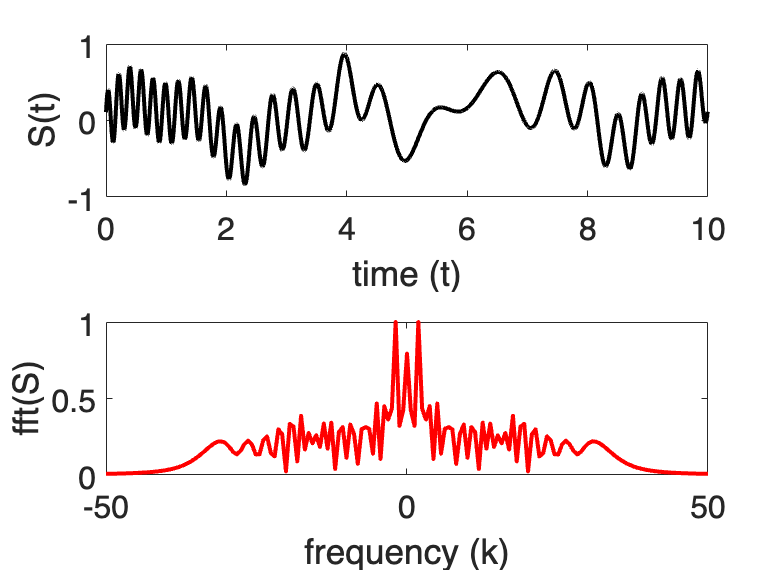

L = 10; n = 2048;
t2 = linspace(0,L,n+1); t = t2(1:n);
k = (2*pi/L)*[0:n/2-1 -n/2:-1];
ks = fftshift(k);

% Create signal
S = (3*sin(2*t) + 0.5*tanh(0.5*(t-3)) + 0.2*exp(-(t-4).^2) ...
    + 1.5*sin(5*t) + 4*cos(3*(t-6).^2))/10 + (t/20).^3;
St = fft(S);

% Plot signal in both time and frequency domain
figure(1)
subplot(2,1,1) % time domain
plot(t,S,'k','Linewidth',2)
set(gca,'Fontsize',16); xlabel('time (t)'); ylabel('S(t)')

subplot(2,1,2) % frequency domain
plot(ks,abs(fftshift(St))/max(abs(St)),'r','Linewidth',2); axis([-50 50 0 1])
set(gca,'Fontsize',16)
xlabel('frequency (k)'), ylabel('fft(S)')

## Plotting a single window

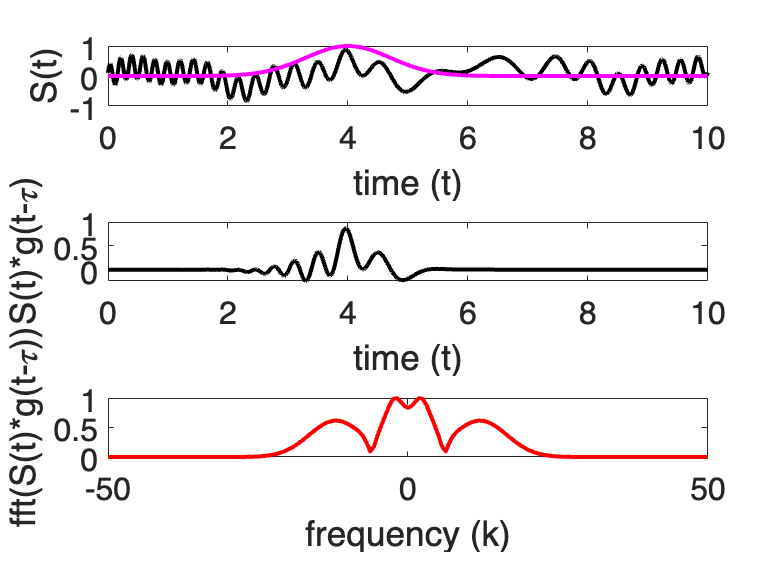

% Window function specs
tau = 4;
a = 1;
g = exp(-a*(t - tau).^2);

% Windowed signal
Sg = g.*S;
Sgt = fft(Sg);

figure(2)
subplot(3,1,1) % Time domain
plot(t,S,'k','Linewidth',2)
hold on
plot(t,g,'m','Linewidth',2)
set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)')

subplot(3,1,2) % Time domain
plot(t,Sg,'k','Linewidth',2)
set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)*g(t-\tau)')

subplot(3,1,3) % Fourier domain
plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r','Linewidth',2); axis([-50 50 0 1])
set(gca,'Fontsize',16), xlabel('frequency (k)'), ylabel('fft(S(t)*g(t-\tau))')

## Plotting a wider window

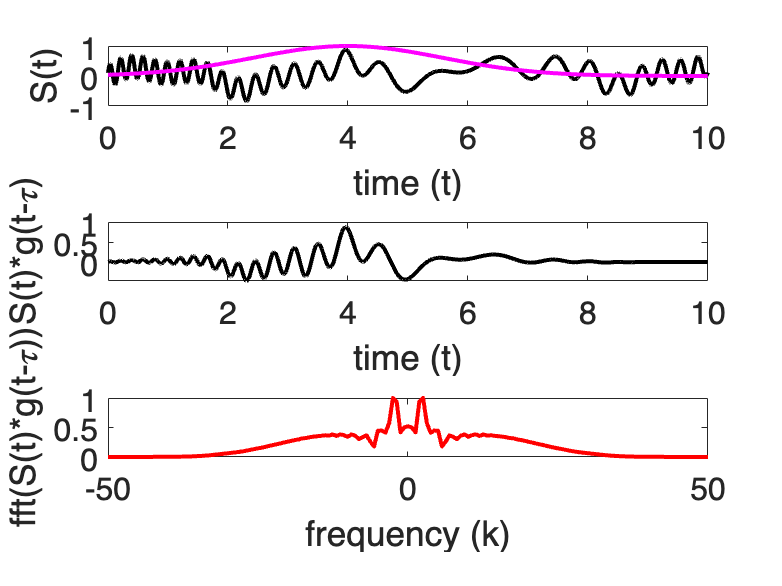

% Window function specs
tau = 4;
a = 0.2;
g = exp(-a*(t - tau).^2);

% Windowed signal
Sg = g.*S;
Sgt = fft(Sg);

figure(3)
subplot(3,1,1) % Time domain
plot(t,S,'k','Linewidth',2)
hold on
plot(t,g,'m','Linewidth',2)
set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)')

subplot(3,1,2) % Time domain
plot(t,Sg,'k','Linewidth',2)
set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)*g(t-\tau)')

subplot(3,1,3) % Fourier domain
plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r','Linewidth',2); axis([-50 50 0 1])
set(gca,'Fontsize',16), xlabel('frequency (k)'), ylabel('fft(S(t)*g(t-\tau))')

## Plotting a thinner window

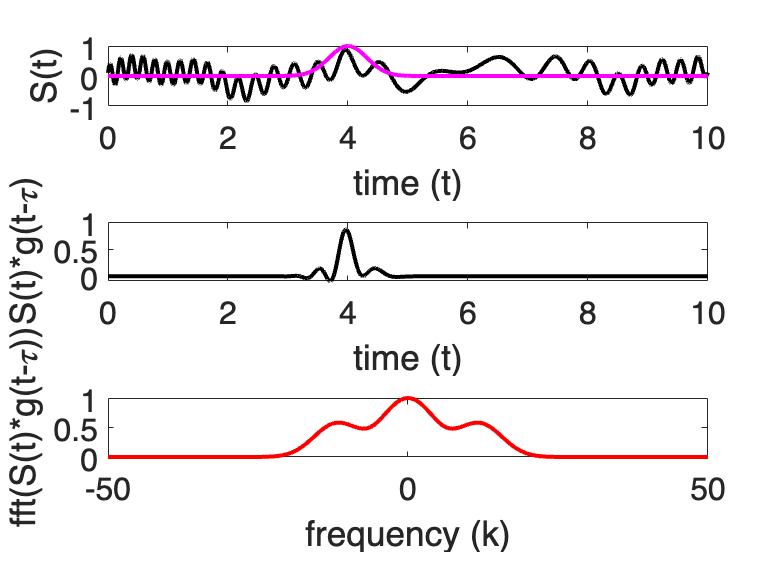

% Window function specs
tau = 4;
a = 5;
g = exp(-a*(t - tau).^2);

% Windowed signal
Sg = g.*S;
Sgt = fft(Sg);

figure(4)
subplot(3,1,1) % Time domain
plot(t,S,'k','Linewidth',2)
hold on
plot(t,g,'m','Linewidth',2)
set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)')

subplot(3,1,2) % Time domain
plot(t,Sg,'k','Linewidth',2)
set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)*g(t-\tau)')

subplot(3,1,3) % Fourier domain
plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r','Linewidth',2); axis([-50 50 0 1])
set(gca,'Fontsize',16), xlabel('frequency (k)'), ylabel('fft(S(t)*g(t-\tau))')

## Sliding the window across the domain

figure(5)
a = 1;
tau = 0:0.1:10;

for j = 1:length(tau)
    g = exp(-a*(t - tau(j)).^2); % Window function
    Sg = g.*S;
    Sgt = fft(Sg);
    
    subplot(3,1,1) % Time domain
    plot(t,S,'k','Linewidth',2)
    hold on
    plot(t,g,'m','Linewidth',2)
    set(gca,'Fontsize',16), xlabel('time (t)'), ylabel('S(t)')
    
    subplot(3,1,2) % Time domain
    plot(t,Sg,'k','Linewidth',2)
    set(gca,'Fontsize',16,'ylim',[-1 1]), xlabel('time (t)'), ylabel('S(t)*g(t-\tau)')
    
    subplot(3,1,3) % Fourier domain
    plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r','Linewidth',2); axis([-50 50 0 1])
    set(gca,'Fontsize',16), xlabel('frequency (k)'), ylabel('fft(S(t)*g(t-\tau))')
    drawnow
    pause
    clf
end

## Creating a spectrogram

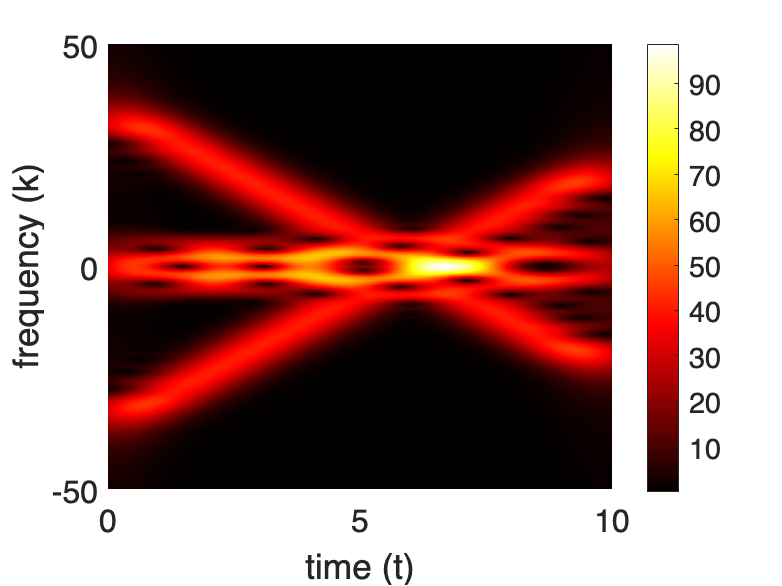

a = 1;
tau = 0:0.1:10;

for j = 1:length(tau)
    g = exp(-a*(t - tau(j)).^2); % Window function
    Sg = g.*S;
    Sgt = fft(Sg);
    Sgt_spec(:,j) = fftshift(abs(Sgt)); % We don't want to scale it
end

figure(6)
pcolor(tau,ks,Sgt_spec)
shading interp
set(gca,'ylim',[-50 50],'Fontsize',16)
colormap(hot)
colorbar
xlabel('time (t)'), ylabel('frequency (k)')

## Comparing spectrograms with different window sizes

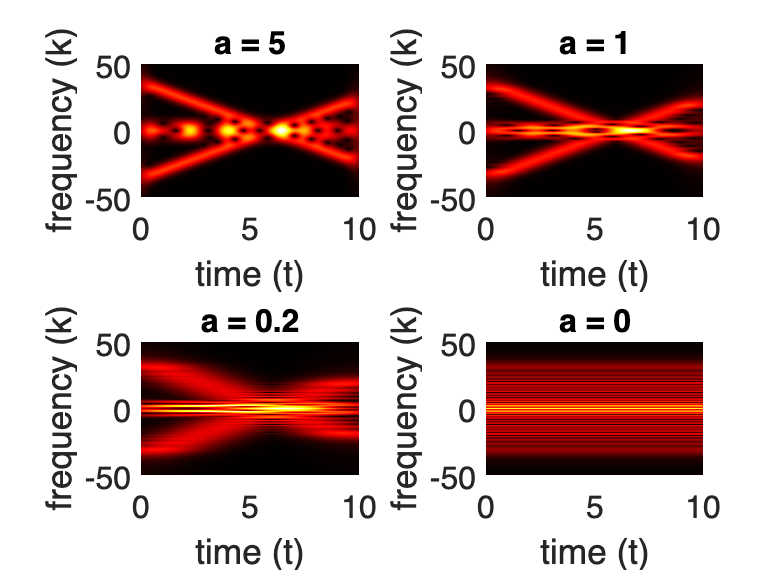

figure(7)

a = [5 1 0.2];
tau = 0:0.1:10;
for jj = 1:length(a)
    Sgt_spec = []; % Clear at each loop iteration
    for j = 1:length(tau)
        g = exp(-a(jj)*(t - tau(j)).^2); % Window function
        Sg = g.*S;
        Sgt = fft(Sg);
        Sgt_spec(:,j) = fftshift(abs(Sgt));
    end
    
    subplot(2,2,jj)
    pcolor(tau,ks,Sgt_spec)
    shading interp
    set(gca,'ylim',[-50 50],'Fontsize',16)
    colormap(hot)
    %colorbar
    xlabel('time (t)'), ylabel('frequency (k)')
    title(['a = ',num2str(a(jj))],'Fontsize',16)
end

% Add in the Fourier transform of the whole signal
Sgt_spec = [];
Sgt_spec = repmat(fftshift(abs(St)),length(tau),1);
subplot(2,2,4)
pcolor(tau,ks,Sgt_spec'),
shading interp
set(gca,'ylim',[-50 50],'Fontsize',16)
colormap(hot)
%colorbar
xlabel('time (t)'), ylabel('frequency (k)')
title('a = 0','Fontsize',16)

## Using MATLAB's spectrogram function

figure(8)

% Trial 1
% spectrogram(S)
% colormap(hot)






















% Trial 2
% spectrogram(S,'yaxis')
% colormap(hot)





















% Trial 3
% spectrogram(S,300,280,'yaxis')
% colormap(hot)






















% Trial 4
% spectrogram(S,300,280,'yaxis')
% colormap(hot)
% set(gca,'Ylim',[0 0.1],'Fontsize',16)






















% Trial 5
% spectrogram(S,300,280,'centered','yaxis')
% colormap(hot)
% set(gca,'Ylim',[-.1 .1],'Fontsize',16)























% Trial 6
% [Sp, w, times] = spectrogram(S,300,280,-50:0.01:50,n/L);
% pcolor(times,w,abs(Sp))
% shading interp
% colormap(hot)
% set(gca,'ylim',[-50,50],'Fontsize',16)

















% Trial 7
% [Sp, w, times] = spectrogram(S,300,280,-50:0.01:50,n/L);
% pcolor(times,w,abs(Sp))
% shading interp
% colormap(hot)
% set(gca,'ylim',[-10,10],'Fontsize',16)

## Comparing spectrograms with different window sizes

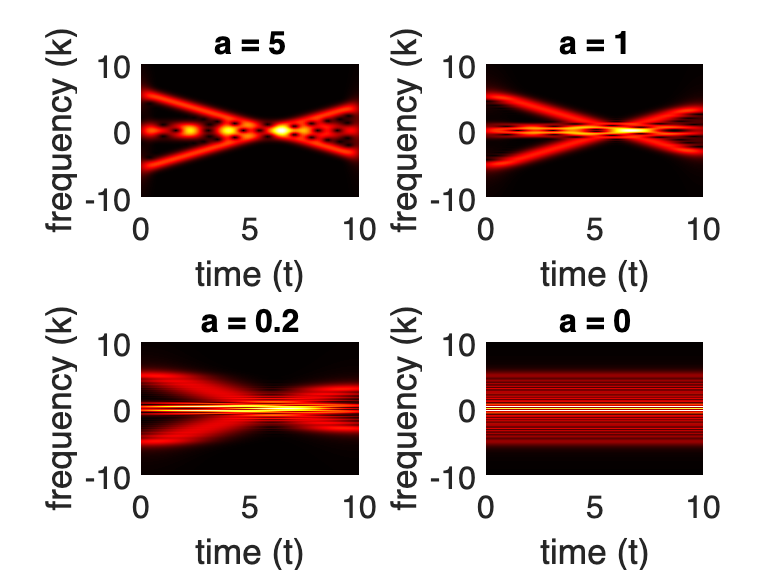

figure(9)

% Different scaling on k
k = (1/L)*[0:n/2-1 -n/2:-1]; % Notice the 1/L instead of 2*pi/L
ks = fftshift(k);

a = [5 1 0.2];
tau = 0:0.1:10;
for jj = 1:length(a)
    Sgt_spec = []; % Clear at each loop iteration
    for j = 1:length(tau)
        g = exp(-a(jj)*(t - tau(j)).^2); % Window function
        Sg = g.*S;
        Sgt = fft(Sg);
        Sgt_spec(:,j) = fftshift(abs(Sgt));
    end
    
    subplot(2,2,jj)
    pcolor(tau,ks,Sgt_spec)
    shading interp
    set(gca,'ylim',[-10 10],'Fontsize',16)
    colormap(hot)
    %colorbar
    xlabel('time (t)'), ylabel('frequency (k)')
    title(['a = ',num2str(a(jj))],'Fontsize',16)
end

% Add in the Fourier transform of the whole signal
Sgt_spec = [];
Sgt_spec = repmat(fftshift(abs(St)),length(tau),1);
subplot(2,2,4)
pcolor(tau,ks,Sgt_spec'),
shading interp
set(gca,'ylim',[-10 10],'Fontsize',16)
colormap(hot)
%colorbar
xlabel('time (t)'), ylabel('frequency (k)')
title('a = 0','Fontsize',16)